clear 
close all

% constants
ts = 1.25e-04;
rate = 8000;
samplelength = 10;
samplesize = rate*samplelength;
amp = 5000;
v_to_mv = 1000;

% load relevant data collected with notch filter off
load julia_notchoff.mat;

ecg_notchoff = (ecg_data / amp) * v_to_mv;
time_notchoff = time;

% load relevant data collected with notch filter on
load julia_notchon.mat;

ecg_notchon = (ecg_data / amp) * v_to_mv;
time_notchon = time;

% plot ECG data
figure
plot(time_notchon, ecg_notchon);
title('Collected ECG data');
xlabel('time in seconds');
xticks()

ans =      0     2     4     6     8    10


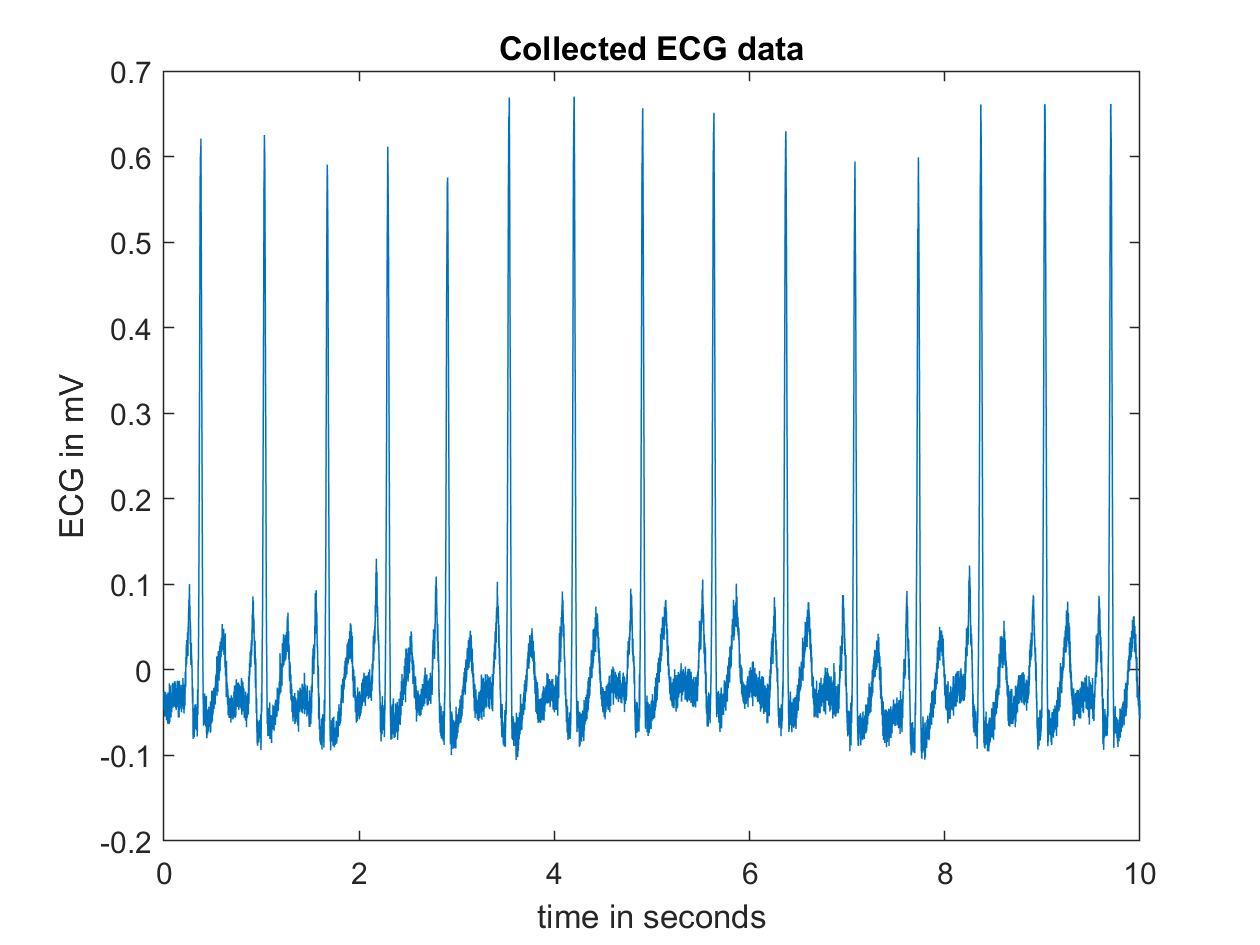

ylabel('ECG in mV');


% plot ECG data
xtickvalues = 0:0.1:2

xtickvalues =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


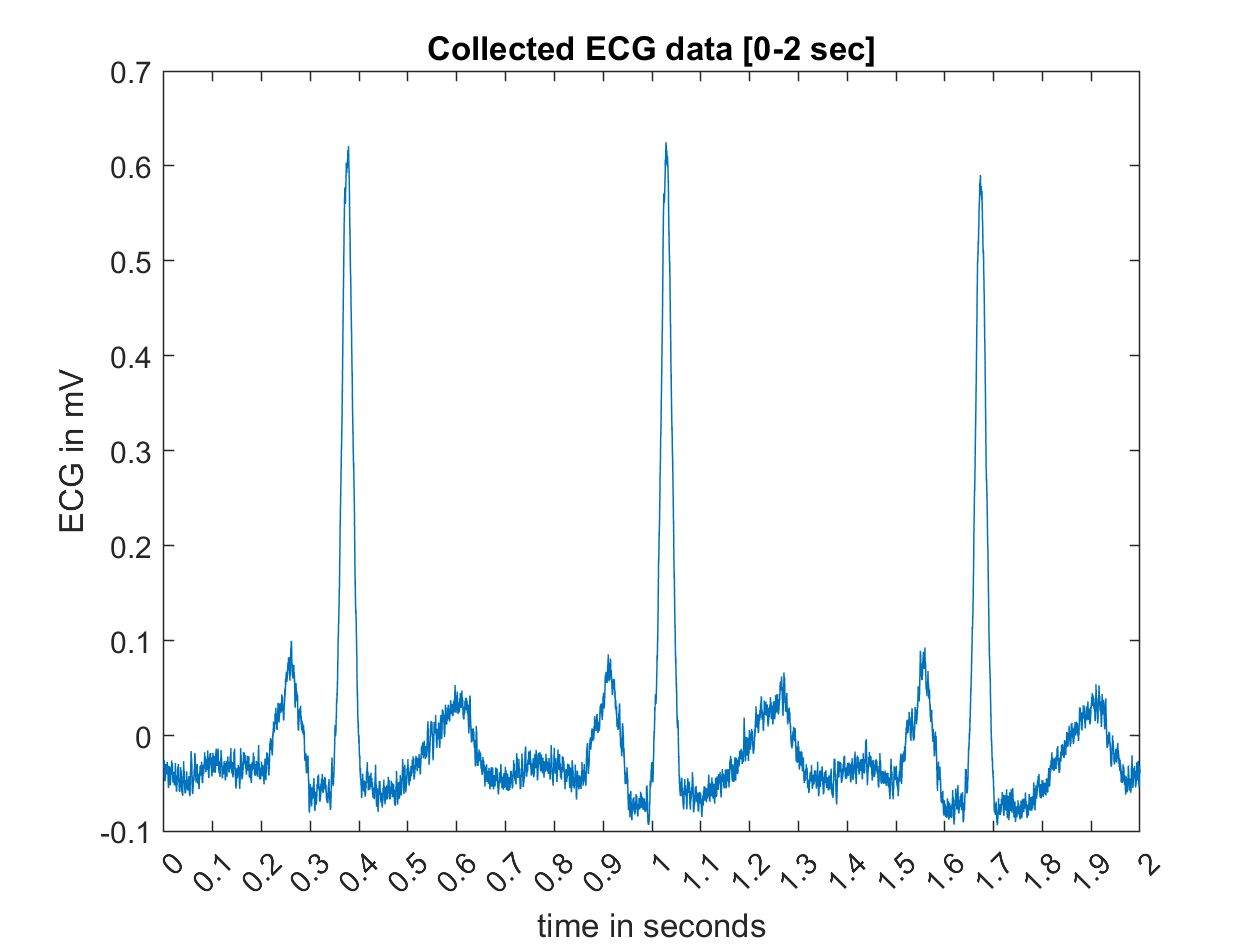

figure
plot(time_notchon, ecg_notchon);
title('Collected ECG data [0-2 sec]');
xlim([0,2])
xticks(xtickvalues);
xlabel('time in seconds');
ylabel('ECG in mV');

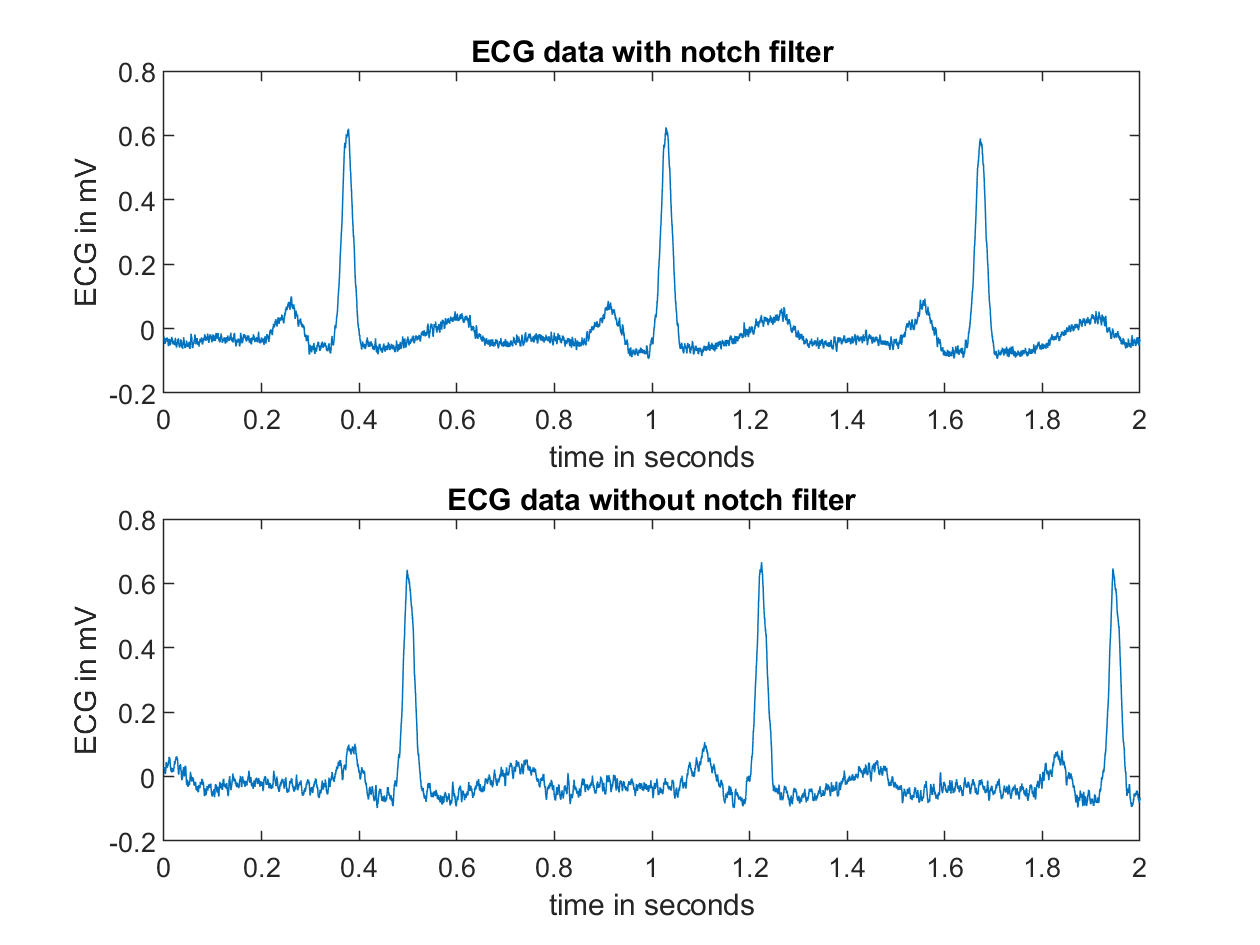


% plot ECG with and without notch filter
figure
subplot(2,1,1)
plot(time_notchon, ecg_notchon);
title('ECG data with notch filter');
xlim([0,2]);
xlabel('time in seconds');
ylabel('ECG in mV');

subplot(2,1,2)
plot(time_notchoff, ecg_notchoff);
title('ECG data without notch filter');
xlim([0,2]);
xlabel('time in seconds');
ylabel('ECG in mV');

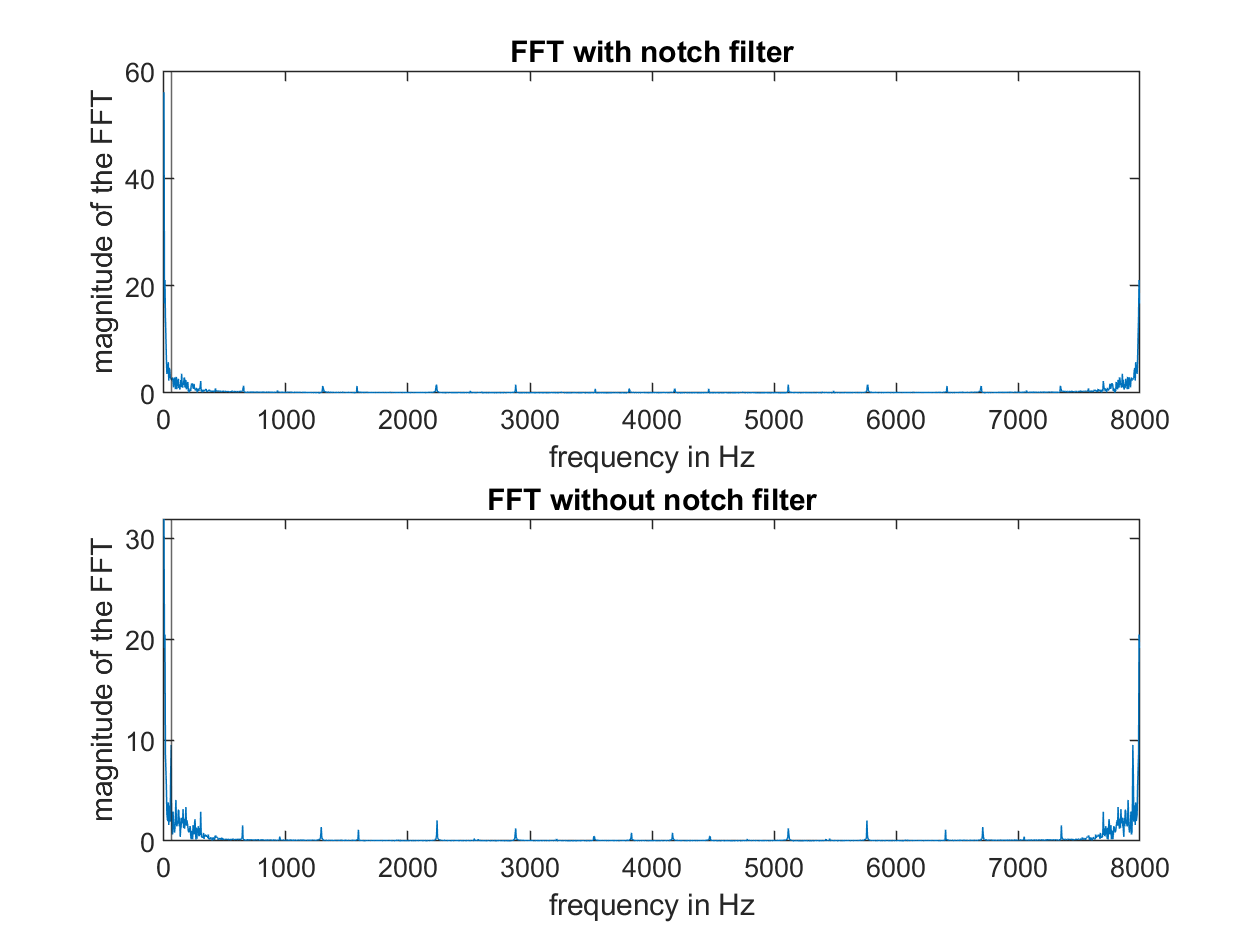



% calculate FFT with and without notch filter

% make sure omega is same length as fft
k = 0:2047;
omega = k*((2*pi)/2048);

% find the fft for each digit
fft_notchon = fft(ecg_notchon,2048);
fft_notchoff = fft(ecg_notchoff,2048);

% convert omega_k to actual frequency in Hz
conversion = rate / (2*pi);
freq = omega * conversion;

% plot FFT with and without notch filter
figure
subplot(2,1,1)
plot(freq, abs(fft_notchon));
xline(60);
title('FFT with notch filter');
xlabel('frequency in Hz');
ylabel('magnitude of the FFT');

subplot(2,1,2)
plot(freq, abs(fft_notchoff));
xline(60);
title('FFT without notch filter');
xlabel('frequency in Hz');
ylabel('magnitude of the FFT');

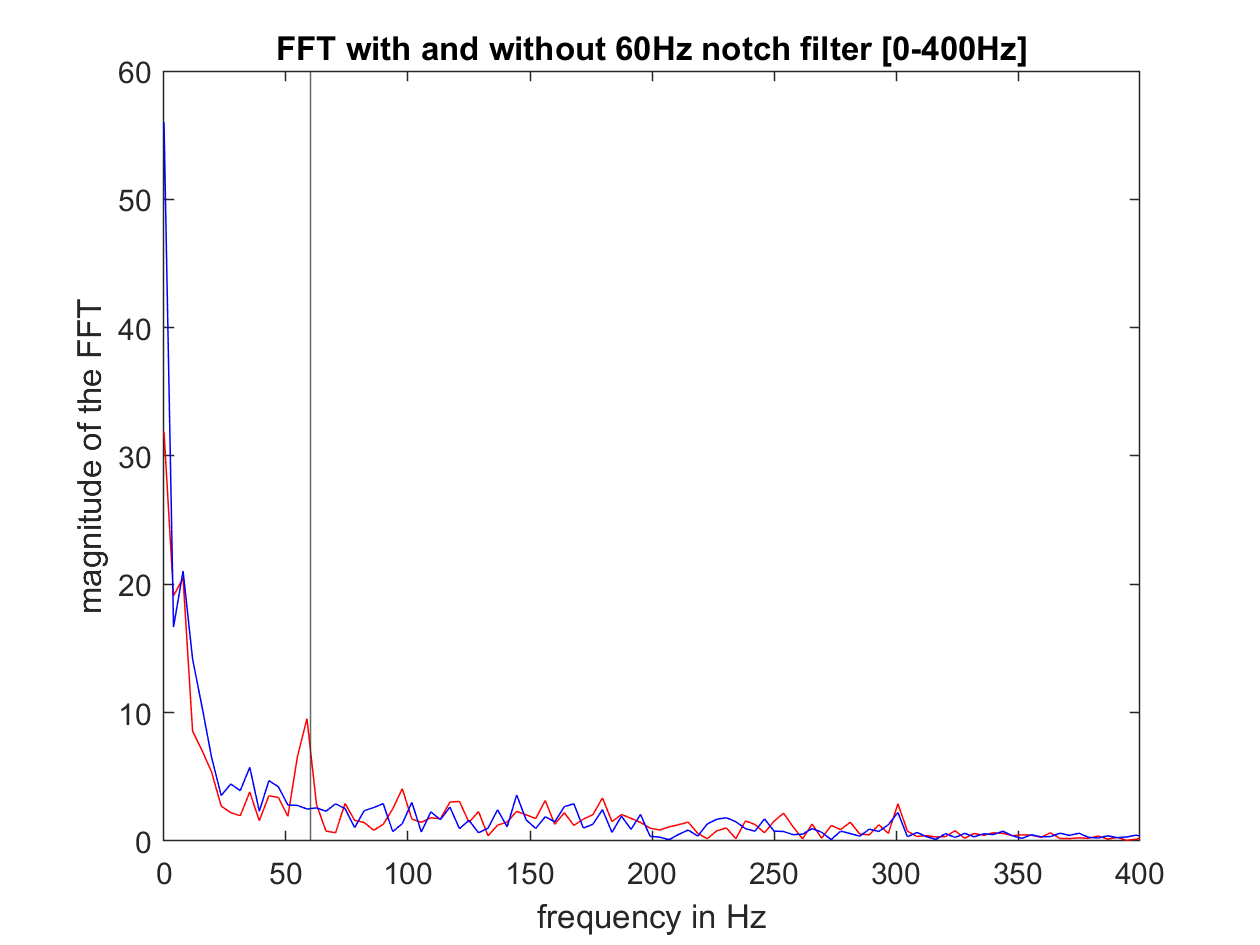


% plot FFT with and without notch filter -- zoomed in at 0-400 Hz
figure
plot(freq, abs(fft_notchoff), 'r-', freq, abs(fft_notchon), 'b-');
xline(60)
title('FFT with and without 60Hz notch filter [0-400Hz]');
xlim([0,400])
xlabel('frequency in Hz');
ylabel('magnitude of the FFT');

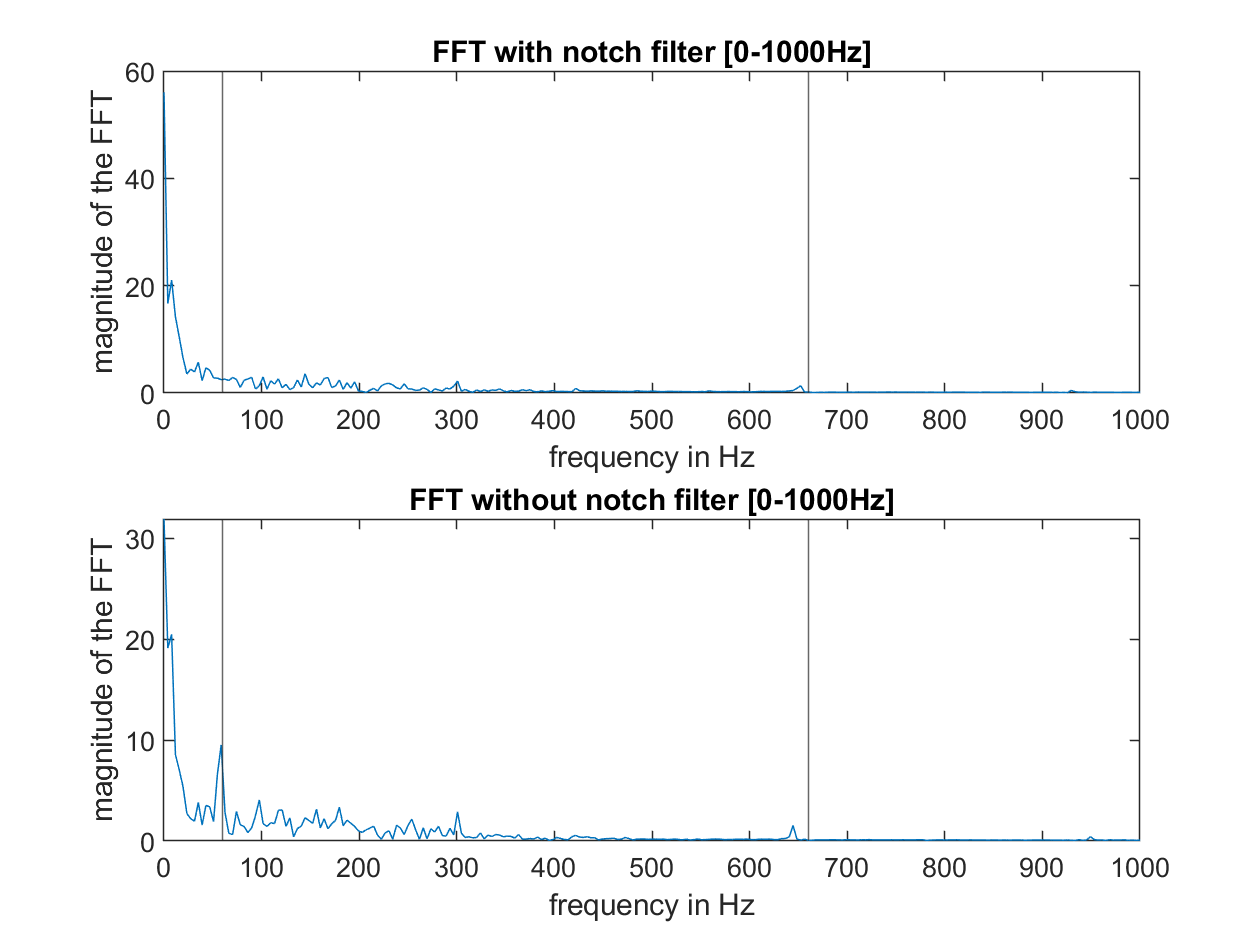


% plot FFT with and without notch filter -- zoomed in at 0-1000 Hz
figure
subplot(2,1,1)
plot(freq, abs(fft_notchon));
xline(60);
xline(660);
title('FFT with notch filter [0-1000Hz]');
xlim([0,1000])
xlabel('frequency in Hz');
ylabel('magnitude of the FFT');

subplot(2,1,2)
plot(freq, abs(fft_notchoff));
xline(60);
xline(660);
title('FFT without notch filter [0-1000Hz]');
xlim([0,1000])
xlabel('frequency in Hz');
ylabel('magnitude of the FFT');